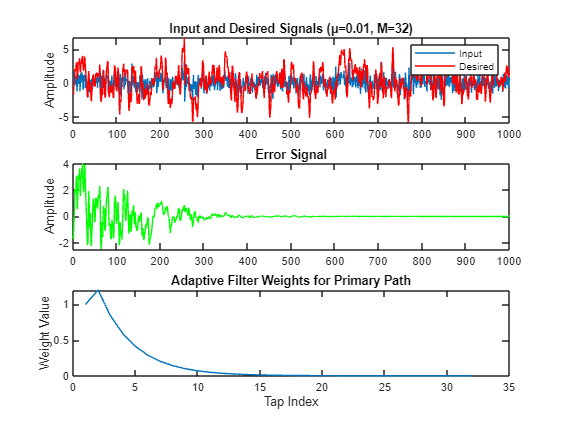

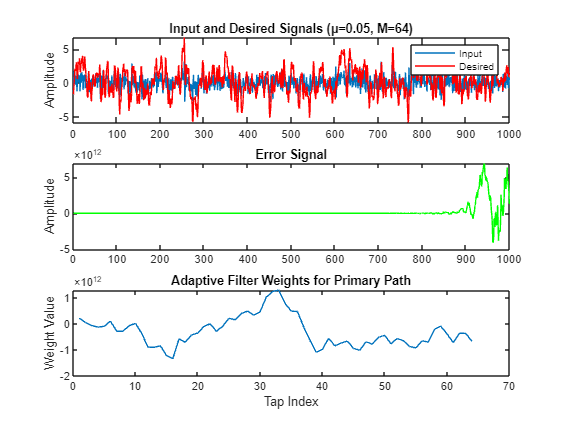

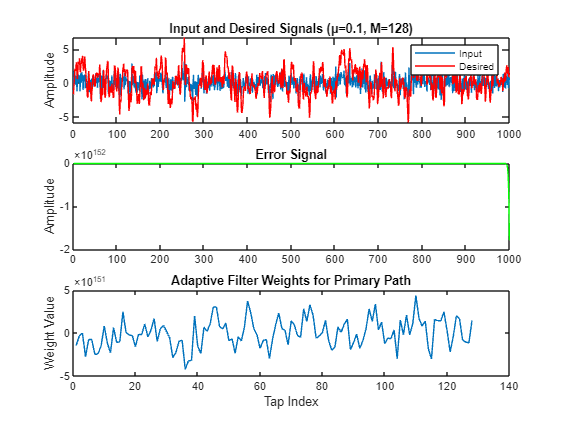

clear all; 
close all; 
clc;

% Parameters for the significant points
significant_points = [
    struct('mu', 0.01, 'M', 32),  % Low μ, Low M
    struct('mu', 0.05, 'M', 64),  % Medium μ, Medium M
    struct('mu', 0.1, 'M', 128)   % High μ, High M
];

% Initialize variables to store results
results = cell(size(significant_points));

% Input signal (noise reference)
x = randn(1000,1);

% Desired signal (noise to be cancelled)
d = filter([1 0.5],[1 -0.7],x);

% Loop over the significant points
for k = 1:numel(significant_points)
    mu = significant_points(k).mu;
    M = significant_points(k).M;
    
    % Initialize weight vectors
    w = zeros(M,1);     % Filter weights for primary path
    w_ref = zeros(M,1); % Filter weights for reference path

    % Buffers
    x_buf = zeros(M,1);
    y_buf = zeros(length(d),1);
    x_ref_buf = zeros(M,1);

    % Main loop
    for n = (M+1):length(x)

        % Shift input buffer
        x_buf = x(n:-1:n-M+1); % Fixed indexing

        % FIR filter output for primary path
        y = w'*x_buf;
        y_buf(n) = y;

        % Shift input buffer for reference path
        x_ref_buf = x(n:-1:n-M+1);

        % FIR filter output for reference path
        y_ref = w_ref'*x_ref_buf;

        % Error signal
        e = d(n) - y;

        % Update weight vectors
        w = w + mu * e * x_buf;
        w_ref = w_ref + mu * e * x_ref_buf;

    end

    % Store results
    results{k} = struct(...
        'mu', mu, ...
        'M', M, ...
        'x', x, ...
        'd', d, ...
        'y_buf', y_buf, ...
        'w', w ...
    );
end

% Plot signals and weights for each significant point
for k = 1:numel(significant_points)
    figure;
    subplot(3,1,1);
    plot(results{k}.x); hold on; plot(results{k}.d,'r'); legend('Input','Desired');
    ylabel('Amplitude');
    title(['Input and Desired Signals (μ=' num2str(results{k}.mu) ', M=' num2str(results{k}.M) ')']);

    subplot(3,1,2);
    plot(results{k}.d-results{k}.y_buf,'g'); 
    ylabel('Amplitude');
    title('Error Signal');

    subplot(3,1,3);
    plot(results{k}.w);
    ylabel('Weight Value');
    xlabel('Tap Index');
    title('Adaptive Filter Weights for Primary Path');
end

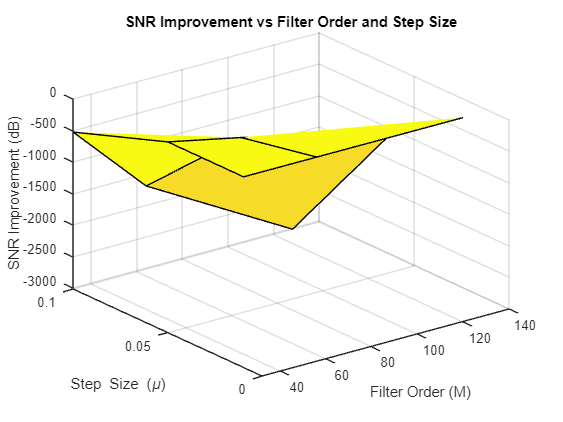


% Parameters for the significant points
significant_M_values = [32, 64, 128];  % Filter length (M)
significant_mu_values = [0.01, 0.05, 0.1];  % Step size (μ)

% Initialize variables to store results
SNR_improvements = zeros(numel(significant_M_values), numel(significant_mu_values));
M_values = zeros(numel(significant_M_values), numel(significant_mu_values));
mu_values = zeros(numel(significant_M_values), numel(significant_mu_values));

% Loop over the significant points
for i = 1:numel(significant_M_values)
    M = significant_M_values(i);
    
    for j = 1:numel(significant_mu_values)
        mu = significant_mu_values(j);
        
        % Initialize weight vectors
        w = zeros(M,1);     % Filter weights for primary path
        w_ref = zeros(M,1); % Filter weights for reference path

        % Buffers
        x_buf = zeros(M,1);
        y_buf = zeros(length(d),1);
        x_ref_buf = zeros(M,1);

        % Main loop
        for n = (M+1):length(x)

            % Shift input buffer
            x_buf = x(n:-1:n-M+1); % Fixed indexing

            % FIR filter output for primary path
            y = w'*x_buf;
            y_buf(n) = y;

            % Shift input buffer for reference path
            x_ref_buf = x(n:-1:n-M+1);

            % FIR filter output for reference path
            y_ref = w_ref'*x_ref_buf;

            % Error signal
            e = d(n) - y;

            % Update weight vectors
            w = w + mu * e * x_buf;
            w_ref = w_ref + mu * e * x_ref_buf;

        end

        % Calculate Signal-to-Noise Ratio (SNR)
        SNR_input = snr(d, d - x); % SNR of input signal
        SNR_output = snr(d, d - y_buf); % SNR of output signal

        % Store SNR improvement
        SNR_improvements(i, j) = SNR_output - SNR_input;
        M_values(i, j) = M;
        mu_values(i, j) = mu;
    end
end

% Create 3D SNR plot
figure;
surf(M_values, mu_values, SNR_improvements);
xlabel('Filter Order (M)');
ylabel('Step Size (\mu)');
zlabel('SNR Improvement (dB)');
title('SNR Improvement vs Filter Order and Step Size');


% Find best μ and M
[max_SNR, idx] = max(SNR_improvements(:));
[best_M_idx, best_mu_idx] = ind2sub(size(SNR_improvements), idx);
best_M = significant_M_values(best_M_idx);
best_mu = significant_mu_values(best_mu_idx);
disp(['Best combination - Step size (μ): ' num2str(best_mu) ', Filter order (M): ' num2str(best_M)]);

Best combination - Step size (μ): 0.05, Filter order (M): 32
